# Тесты

## Тест 1

format long;
x_0 = -1;
x_n = 1;
t = sym('t');
q =@(t)(-(1+t/2).*(t-3));
r =@(t)(exp(t/2).*(t-3));
f =@(t)(-(2-t).*(t-3));
alpha = [1 0 0];
beta = [1 0 0];
syms u(t);
Du = diff(u);

Решаем следующий дифур:

diff(u,2) + q*diff(u) - r*u == f

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}u\left(t\right)-\left(\frac{t}{2}+1\right)\,\left(t-3\right)\,\frac{\partial }{\partial t}u\left(t\right)-{\mathrm{e}}^{t/2}\,u\left(t\right)\,\left(t-3\right)=\left(t-2\right)\,\left(t-3\right)$$

Краевые условия:

alpha(1)*u(-1)-alpha(2)*Du(-1) == alpha(3)

$$ans = u\left(-1\right)=0$$

beta(1)*u(1)+beta(2)*Du(1) == beta(3)

$$ans = u\left(1\right)=0$$

Точное решение:

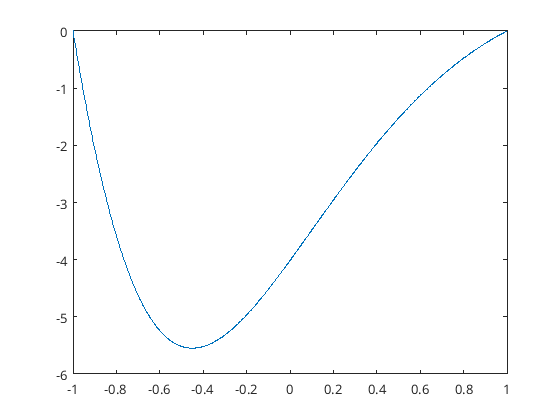

fun = @(x,y) [y(2); (1+x/2)*(x-3)*y(2)+(exp(x/2)*(x-3))*y(1)-(2-x)*(x-3)];
bc = @(ya, yb) [ya(1); yb(1)];
xmesh = linspace(-1, 1, 1000);
solinit = bvpinit(xmesh, [0 1]);
sol = bvp4c(fun, bc, solinit);
plot(sol.x,sol.y(1,:));

Численное решение:

epsilon = 1e-6;
[u_ch, x_ch, d] = Richardson(x_0, x_n, q, r, f, alpha, beta,epsilon);

Количество итераций:
    11



%h = x(2) - x(1);

Погрешность:

d

d =      2.925574461206300e-07


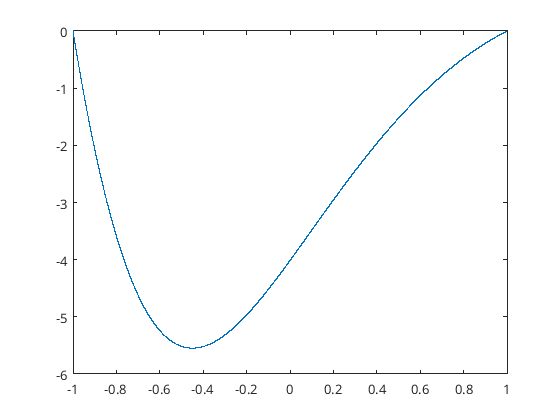

%[u_ch,x_ch] = net_met(x_0, h, x_n, q, r, f, alpha, beta);
plot(x_ch,u_ch);

На одном графике:

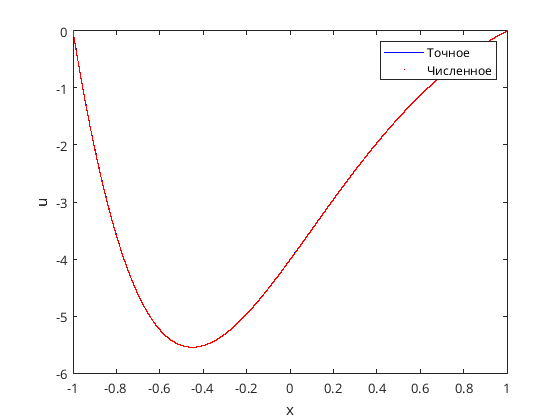

plot(sol.x,sol.y(1,:),'-b',x_ch,u_ch,'r.','MarkerSize',1);
ylabel('u');
xlabel('x');
legend('Точное', 'Численное');

## Тест 2

format long;
x_0 = -1;
x_n = 1;
t = sym('t');
q =@(t)(-(1+t/2).*(5+2*t)./(4 + t));
r =@(t)((1 + exp(t/2)).*(5+2*t)./(4 + t));
f =@(t)(-(2+t).*(5+2*t)./(4 + t));
alpha = [0.5 1 -0.2];
beta = [0.3 1 -0.3];
syms u(t);
Du = diff(u);

Решаем следующий дифур:

diff(u,2) + q*diff(u) - r*u == f

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}u\left(t\right)-\frac{u\left(t\right)\,\left(2\,t+5\right)\,\left({\mathrm{e}}^{t/2}+1\right)}{t+4}-\frac{\left(\frac{t}{2}+1\right)\,\left(2\,t+5\right)\,\frac{\partial }{\partial t}u\left(t\right)}{t+4}=-\frac{\left(2\,t+5\right)\,\left(t+2\right)}{t+4}$$

Краевые условия:

alpha(1)*u(-1)-alpha(2)*Du(-1) == alpha(3)

$$ans = \frac{u\left(-1\right)}{2}-\left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=-1}\right)=-\frac{1}{5}$$

beta(1)*u(1)+beta(2)*Du(1) == beta(3)

$$ans = \frac{3\,u\left(1\right)}{10}+\left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=1}\right)=-\frac{3}{10}$$

Точное решение:

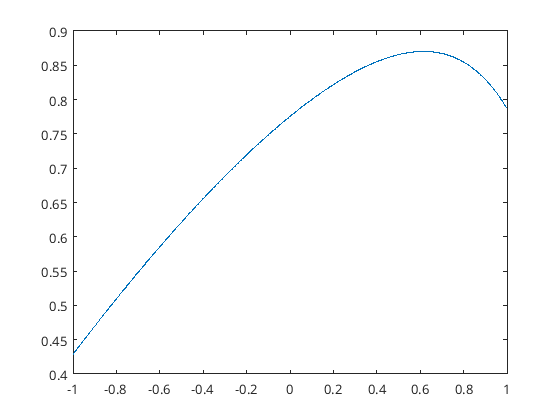

fun = @(x,y) [y(2); 
    (1+x/2)*(5+2*x)/(4 + x)*y(2)+((1 + exp(x/2))*(5+2*x)/(4 + x))*y(1)-(2+x)*(5+2*x)/(4 + x)];
bc = @(ya, yb) [0.5*ya(1)-ya(2) + 0.2; 0.3*yb(1) + yb(2) + 0.3];
xmesh = linspace(-1, 1, 1000);
solinit = bvpinit(xmesh, [0 1]);
sol = bvp4c(fun, bc, solinit);
plot(sol.x,sol.y(1,:));

Численное решение:

epsilon = 1e-6;
[u_ch, x_ch, d] = Richardson(x_0, x_n, q, r, f, alpha, beta,epsilon);

Количество итераций:
     9



%h = x(2) - x(1);

Погрешность:

d

d =      4.924936665891740e-07


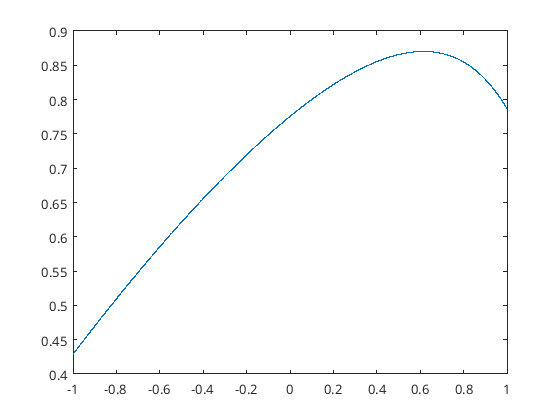

%[u_ch,x_ch] = net_met(x_0, h, x_n, q, r, f, alpha, beta);
plot(x_ch,u_ch);

На одном графике:

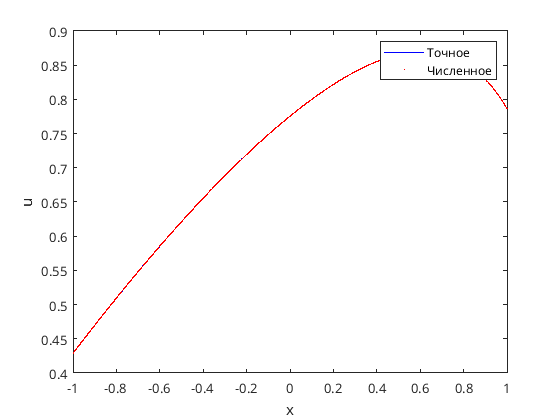

plot(sol.x,sol.y(1,:),'-b',x_ch,u_ch,'r.','MarkerSize',1);
ylabel('u');
xlabel('x');
legend('Точное', 'Численное');

## Тест 3

format long;
x_0 = -1;
x_n = 1;
t = sym('t');
q =@(t)((1-t/2).*(7+3*t)./(6+t));
r =@(t)((1+cos(t)/2).*(7+3*t)./(6+t));
f =@(t)(-(1-t/3).*(7+3*t)./(6+t));
alpha = [-2 -1 0];
beta = [0 1 0];
syms u(t);
Du = diff(u);

Решаем следующий дифур:

diff(u,2) + q*diff(u) - r*u == f

$$ans(t) = \frac{\partial^{2}}{\partial t^{2}}u\left(t\right)-\frac{u\left(t\right)\,\left(3\,t+7\right)\,\left(\frac{\cos\left(t\right)}{2}+1\right)}{t+6}-\frac{\left(\frac{t}{2}-1\right)\,\left(3\,t+7\right)\,\frac{\partial }{\partial t}u\left(t\right)}{t+6}=\frac{\left(\frac{t}{3}-1\right)\,\left(3\,t+7\right)}{t+6}$$

Краевые условия:

alpha(1)*u(-1)-alpha(2)*Du(-1) == alpha(3)

$$ans = \left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=-1}\right)-2\,u\left(-1\right)=0$$

beta(1)*u(1)+beta(2)*Du(1) == beta(3)

$$ans = \left({\left(\frac{\partial }{\partial t}u\left(t\right)\right)|}_{t=1}\right)=0$$

Точное решение:

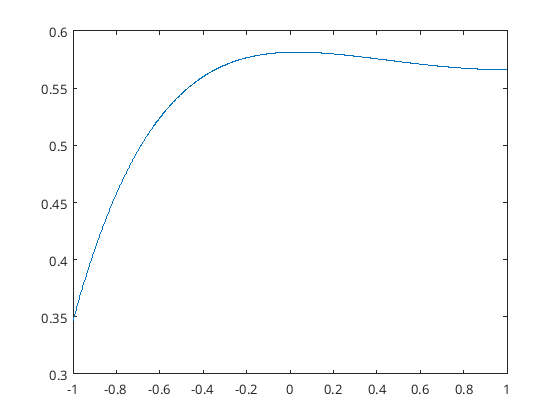

fun = @(x,y) [y(2); ...
    -(1-x/2)*(7+3*x)/(6 + x)*y(2)+((1 + cos(x)/2)*(7+3*x)/(6 + x))*y(1)-(1-x/3)*(7+3*x)/(6 + x)];
bc = @(ya, yb) [-2*ya(1)+ya(2); yb(2)];
xmesh = linspace(-1, 1, 1000);
solinit = bvpinit(xmesh, [0 1]);
sol = bvp4c(fun, bc, solinit);
plot(sol.x,sol.y(1,:));

Численное решение:

epsilon = 1e-6;
[u_ch, x_ch, d] = Richardson(x_0, x_n, q, r, f, alpha, beta,epsilon);

Количество итераций:
     8



%h = x(2) - x(1);

Погрешность:

d

d =      4.150550874104653e-07


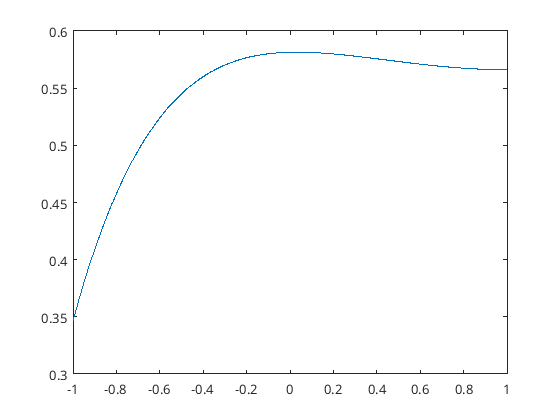

%[u_ch,x_ch] = net_met(x_0, h, x_n, q, r, f, alpha, beta);
plot(x_ch,u_ch);

На одном графике:

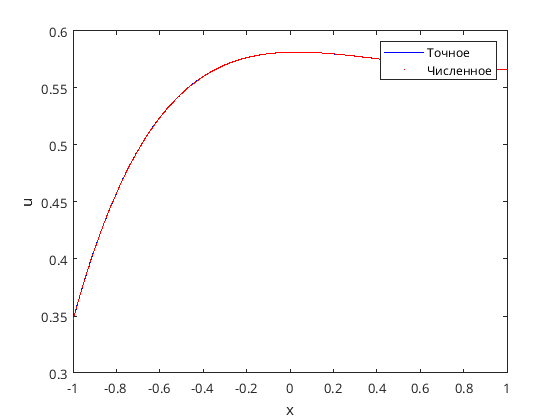

plot(sol.x,sol.y(1,:),'-b',x_ch,u_ch,'r.','MarkerSize',1);
ylabel('u');
xlabel('x');
legend('Точное', 'Численное');